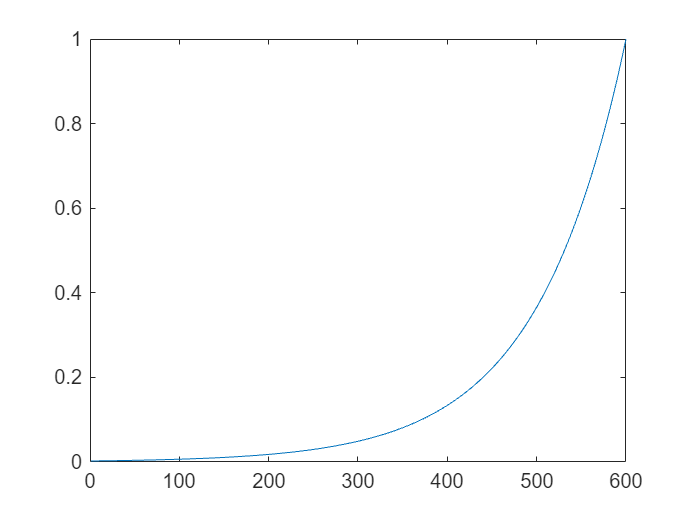

% 用误差权重训练神经网络
% 在默认的均方误差性能函数中（请参阅训练和应用多层浅层神经网络），每个平方误差对性能函数的贡献量相同
% 但是，工具箱允许您按如下方式单独加权每个平方误差：误差加权对象需要与目标数据具有相同的维度。
% 这样，可以根据时间步长、样本数、信号数或元素数对误差进行加权。
% 以下是对时间序列末尾的误差加权比时间序列开头的误差更重的示例。
% 误差加权对象作为调用 train 的最后一个参数传递。

% Train Neural Networks with Error Weights
% In the default mean square error performance function (see Train and Apply Multilayer Shallow Neural Networks), each squared error contributes the same amount to the performance function as follows:
% However, the toolbox allows you to weight each squared error individually as follows:
% The error weighting object needs to have the same dimensions as the target data. 
% In this way, errors can be weighted
% according to time step, sample number, signal number or element number. 
% The following is an example of weighting the errors 
% at the end of a time sequence more heavily than errors at the beginning of a time sequence. 
% The error weighting object is passed as the last argument in the call to train.

y = laser_dataset;
y = y(1:600);
ind = 1:600;
ew = 0.99.^(600-ind);
figure
plot(ew)

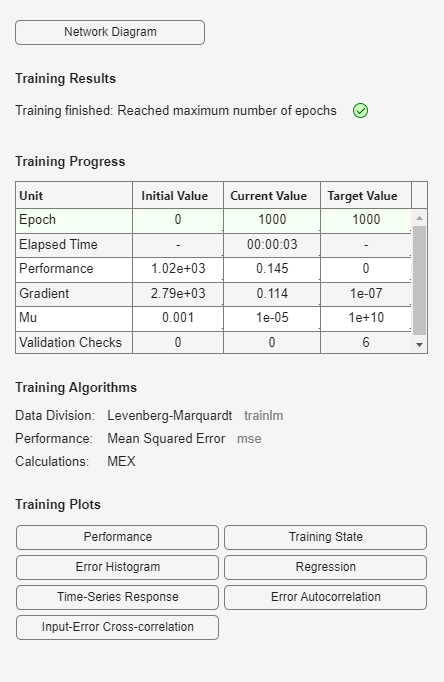

% Figure contains an axes object. The axes object contains an object of type line.

ew = con2seq(ew);
ftdnn_net = timedelaynet([1:8],10);
ftdnn_net.trainParam.epochs = 1000;
ftdnn_net.divideFcn = '';
[p,Pi,Ai,t,ew1] = preparets(ftdnn_net,y,y,{},ew);
[ftdnn_net1,tr] = train(ftdnn_net,p,t,Pi,Ai,ew1);

% 该图说明了此示例的误差加权。
% 训练数据有600个时间步，误差呈指数加权，
% 最后一个平方误差的权重为 1，
% 以及第一个时间步长的平方误差的权重为 0.0024。
% The figure illustrates the error weighting for this example. 
% There are 600 time steps in the training data, and the errors are weighted exponentially,
% with the last squared error having a weight of 1, 
% and the squared error at the first time step having a weighting of 0.0024.

% 训练好的网络的响应如下图所示。
% 如果将此响应与网络的响应进行比较
% 在没有对平方误差进行指数加权的情况下进行训练，
% 如 Design Time Series Time-Delay Neural Networks 所示，
% 您可以看到序列中后期的误差小于序列中较早的误差。
% 后来发生的误差更小，因为它们对加权性能指数的贡献大于早期误差。
% The response of the trained network is shown in the following figure.
% If you compare this response to the response of the network 
% that was trained without exponential weighting on the squared errors, 
% as shown in Design Time Series Time-Delay Neural Networks, 
% you can see that the errors late in the sequence are smaller than the errors earlier in the sequence. 
% The errors that occurred later are smaller 
% because they contributed more to the weighted performance index than earlier errors.